# DEEP LEARNING-BASED VISION ALGORITHMS

trainPath = 'D:\Study\DYPU\SEM\sem7\ITWSM\ITWSM_LAB\archive\train\train'; % Contains 33 subfolders
testPath = 'D:\Study\DYPU\SEM\sem7\ITWSM\ITWSM_LAB\archive\test\test';      % Contains test images

imds_train = imageDatastore(trainPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

fprintf('Total available images: %d\n', numel(imds_train.Files));

Total available images: 16854


fprintf('Number of classes: %d\n', numel(categories(imds_train.Labels)));

Number of classes: 33


%% Step 2: Reduce Dataset (Change 0.3 to 0.5 or 1.0 for more data)
percentageToUse = 0.3;  % 30% of data
imds_train_reduced = splitEachLabel(imds_train, percentageToUse);

fprintf('\n=== Dataset Reduction ===\n');


=== Dataset Reduction ===


fprintf('Using %.0f%% of data for faster training\n', percentageToUse * 100);

Using 30% of data for faster training


fprintf('Reduced dataset size: %d images\n', numel(imds_train_reduced.Files));

Reduced dataset size: 5061 images


labelCount = countEachLabel(imds_train_reduced);
disp(labelCount);

          Label           Count
    __________________    _____

    Apple Braeburn         148 
    Apple Granny Smith     148 
    Apricot                148 
    Avocado                128 
    Banana                 147 
    Blueberry              139 
    Cactus fruit           147 
    Cantaloupe             148 
    Cherry                 148 
    Clementine             147 
    Corn                   135 
    Cucumber Ripe          118 
    Grape Blue             295 
    Kiwi                   140 
    Lemon                  148 
    Limes                  147 
    Mango                  147 
    Onion White            131 
    Orange                 144 
    Papaya                 148 
    Passion Fruit          147 
    Peach                  148 
    Pear                   209 
    Pepper Green           133 
    Pepper Red             200 
    Pineapple              147 
    Plum                   134 
   

%% Step 3: Split into Train/Validation (80/20)
[imdsTrain, imdsValidation] = splitEachLabel(imds_train_reduced, 0.8, 'randomized');

fprintf('\nTraining images: %d\n', numel(imdsTrain.Files));


Training images: 4046


fprintf('Validation images: %d\n\n', numel(imdsValidation.Files));

Validation images: 1015



%% Step 4: Load SqueezeNet
fprintf('=== Loading SqueezeNet ===\n');

=== Loading SqueezeNet ===


net = squeezenet;
inputSize = net.Layers(1).InputSize;
fprintf('✓ Loaded: SqueezeNet\n');

✓ Loaded: SqueezeNet


fprintf('Input size required: %dx%d\n\n', inputSize(1), inputSize(2));

Input size required: 227x227



%% Step 5: Data Augmentation
imageAugmenter = imageDataAugmenter( ...
    'RandRotation', [-20, 20], ...
    'RandXReflection', true, ...
    'RandYReflection', true, ...
    'RandXTranslation', [-10 10], ...
    'RandYTranslation', [-10 10], ...
    'RandScale', [0.9 1.1]);

augimdsTrain = augmentedImageDatastore(inputSize, imdsTrain, ...
    'DataAugmentation', imageAugmenter, ...
    'ColorPreprocessing', 'gray2rgb');

augimdsValidation = augmentedImageDatastore(inputSize, imdsValidation, ...
    'ColorPreprocessing', 'gray2rgb');

%% Step 6: Modify Network for 33 Classes
lgraph = layerGraph(net);
numClasses = numel(categories(imdsTrain.Labels));

% Replace conv10 layer (SqueezeNet specific)
newConvLayer = convolution2dLayer([1, 1], numClasses, ...
    'Name', 'conv10_new', ...
    'WeightLearnRateFactor', 10, ...
    'BiasLearnRateFactor', 10);
lgraph = replaceLayer(lgraph, 'conv10', newConvLayer);
fprintf('✓ Replaced layer: conv10 (1000 → %d classes)\n', numClasses);

✓ Replaced layer: conv10 (1000 → 33 classes)


% Replace classification layer
newClassLayer = classificationLayer('Name', 'ClassificationLayer_predictions_new');
lgraph = replaceLayer(lgraph, 'ClassificationLayer_predictions', newClassLayer);
fprintf('✓ Replaced layer: ClassificationLayer_predictions\n');

✓ Replaced layer: ClassificationLayer_predictions


%% Step 7: Training Configuration
fprintf('\n=== Training Configuration ===\n');


=== Training Configuration ===


fprintf('Mini-batch size: 32\n');

Mini-batch size: 32


fprintf('Max epochs: 10\n');

Max epochs: 10


fprintf('Learning rate: 1.00e-04\n\n');

Learning rate: 1.00e-04



options = trainingOptions('sgdm', ...
    'MiniBatchSize', 32, ...
    'MaxEpochs', 10, ...
    'InitialLearnRate', 1e-4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augimdsValidation, ...
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'VerboseFrequency', 10, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'auto');

if canUseGPU()
    fprintf('GPU: Available ✓ (Training will be MUCH faster)\n');
    fprintf('Expected training time: 5-10 minutes\n');
else
    fprintf('GPU: Not available (Training on CPU)\n');
    fprintf('Expected training time: 10-20 minutes\n');
end

GPU: Available ✓ (Training will be MUCH faster)


Expected training time: 5-10 minutes


%% Step 8: Train Network
fprintf('\n=== Starting Training ===\n');


=== Starting Training ===


fprintf('Training with %d images...\n\n', numel(imdsTrain.Files));

Training with 4046 images...



Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |        0.00% |        1.28% |       9.6724 |       8.3048 |      1.0000e-04 |
|       1 |          10 |       00:00:06 |        0.00% |              |       3.8196 |              |      1.0000e-04 |
|       1 |          20 |       00:00:07 |        6.25% |              |       3.5962 |              |      1.0000e-04 |
|       1 |          30 |       00:00:10 |       15.62% |       20.00% |       3.2109 |   

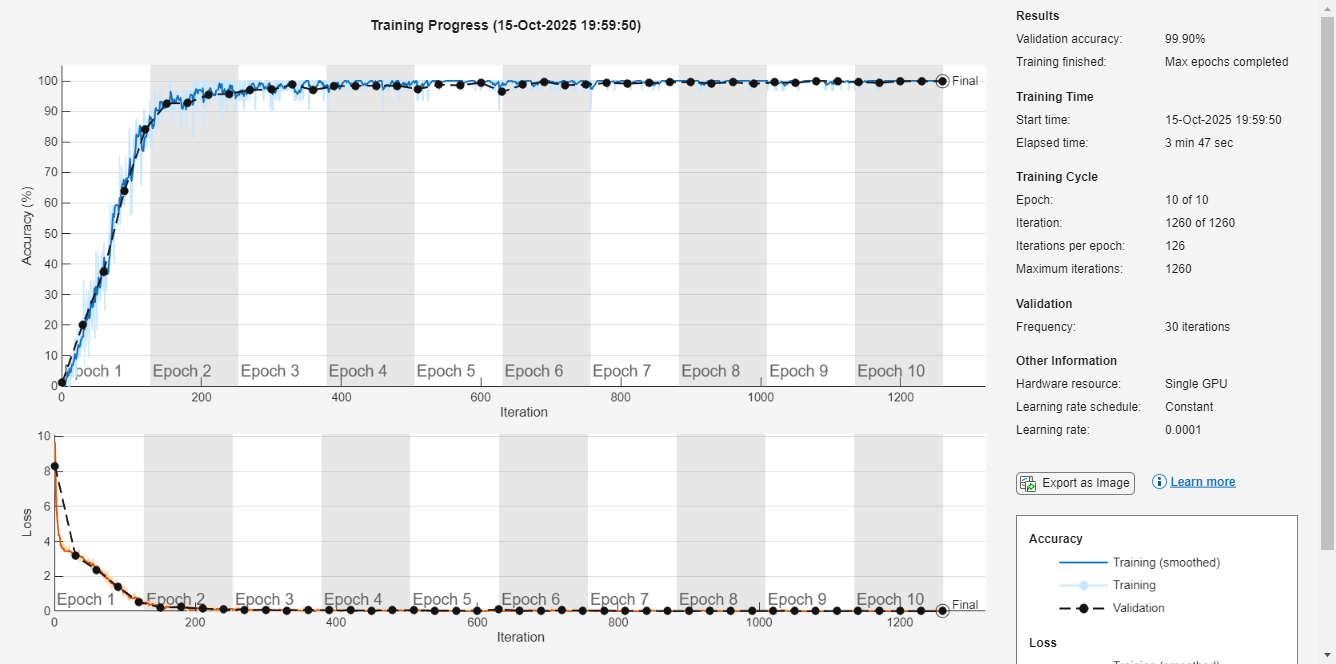


tic;
netTransfer = trainNetwork(augimdsTrain, lgraph, options);

trainingTime = toc;

save('fruit_veg_classifier.mat', 'netTransfer');
fprintf('\n✓ Model saved as: fruit_veg_classifier.mat\n');


✓ Model saved as: fruit_veg_classifier.mat


fprintf('✓ Training completed in %.1f minutes\n', trainingTime/60);

✓ Training completed in 4.0 minutes



%% Step 9: Evaluate on Validation Set
fprintf('\n=== Evaluating on Validation Set ===\n');


=== Evaluating on Validation Set ===



predictedLabels = classify(netTransfer, augimdsValidation);
valLabels = imdsValidation.Labels;

accuracy = sum(predictedLabels == valLabels) / numel(valLabels);
fprintf('Validation Accuracy: %.2f%%\n', accuracy * 100);

Validation Accuracy: 99.90%


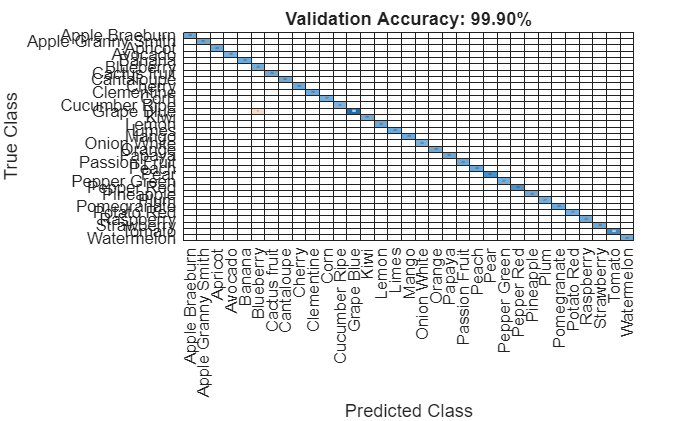


figure('Name', 'Confusion Matrix - Validation Set');
confusionchart(valLabels, predictedLabels);
title(sprintf('Validation Accuracy: %.2f%%', accuracy * 100));

%% Step 10: Test Set Predictions
fprintf('\n=== Classifying Test Images ===\n');


=== Classifying Test Images ===



if exist(testPath, 'dir')
    testFiles = dir(fullfile(testPath, '*.jpg'));
    if isempty(testFiles)
        testFiles = dir(fullfile(testPath, '*.png'));
    end
    
    numTestImages = length(testFiles);
    
    if numTestImages > 0
        fprintf('Found %d test images\n', numTestImages);
        
        predictedLabels_test = strings(numTestImages, 1);
        testImageNames = cell(numTestImages, 1);
        confidenceScores = zeros(numTestImages, 1);
        
        fprintf('Processing test images...\n');
        
        for i = 1:numTestImages
            img = imread(fullfile(testPath, testFiles(i).name));
            
            if size(img, 3) == 1
                img = cat(3, img, img, img);
            end
            
            img = imresize(img, inputSize(1:2));
            
            [label, scores] = classify(netTransfer, img);
            predictedLabels_test(i) = string(label);
            testImageNames{i} = testFiles(i).name;
            confidenceScores(i) = max(scores);
            
            if mod(i, 500) == 0
                fprintf('Processed %d/%d images\n', i, numTestImages);
            end
        end
        
        resultsTable = table(testImageNames, predictedLabels_test, confidenceScores, ...
            'VariableNames', {'ImageName', 'PredictedClass', 'Confidence'});
        writetable(resultsTable, 'classification_results.csv');
        
        fprintf('✓ Results saved to: classification_results.csv\n');
        
        fprintf('\n=== Sample Predictions ===\n');
        numSamples = min(10, numTestImages);
        for i = 1:numSamples
            fprintf('%s -> %s (%.1f%% confidence)\n', ...
                testImageNames{i}, ...
                predictedLabels_test(i), ...
                confidenceScores(i) * 100);
        end
    else
        fprintf('Warning: No test images found\n');
    end
else
    fprintf('Warning: Test path does not exist\n');
end

Found 5641 test images


Processing test images...


Processed 500/5641 images
Processed 1000/5641 images
Processed 1500/5641 images
Processed 2000/5641 images
Processed 2500/5641 images
Processed 3000/5641 images
Processed 3500/5641 images
Processed 4000/5641 images
Processed 4500/5641 images
Processed 5000/5641 images
Processed 5500/5641 images


✓ Results saved to: classification_results.csv



=== Sample Predictions ===


0000.jpg -> Apricot (100.0% confidence)
0001.jpg -> Grape Blue (100.0% confidence)
0002.jpg -> Mango (100.0% confidence)
0003.jpg -> Grape Blue (100.0% confidence)
0004.jpg -> Mango (100.0% confidence)
0005.jpg -> Watermelon (100.0% confidence)
0006.jpg -> Apricot (100.0% confidence)
0007.jpg -> Mango (100.0% confidence)
0008.jpg -> Grape Blue (100.0% confidence)
0009.jpg -> Potato Red (100.0% confidence)


%% Step 11: Visualize Sample Predictions
fprintf('\n=== Visualizing Sample Predictions ===\n');


=== Visualizing Sample Predictions ===


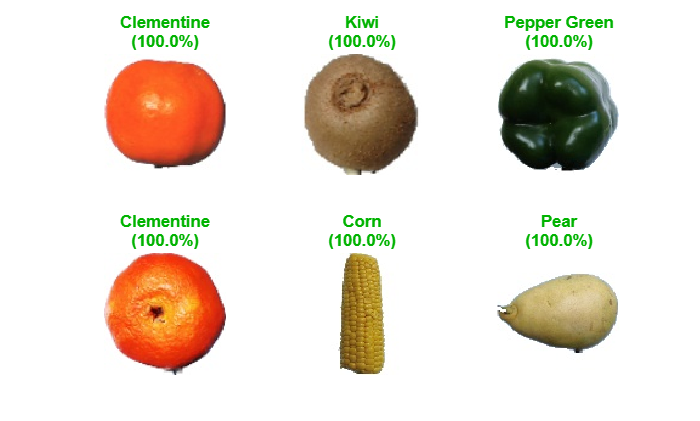


figure('Name', 'Sample Predictions');
numSamples = min(6, numel(imdsValidation.Files));
sampleIdx = randperm(numel(imdsValidation.Files), numSamples);

for i = 1:numSamples
    img = readimage(imdsValidation, sampleIdx(i));
    img_resized = imresize(img, inputSize(1:2));
    
    [predictedLabel, scores] = classify(netTransfer, img_resized);
    trueLabel = imdsValidation.Labels(sampleIdx(i));
    
    subplot(2, 3, i);
    imshow(img);
    
    if predictedLabel == trueLabel
        titleColor = [0 0.7 0];
        titleText = sprintf('%s\n(%.1f%%)', string(predictedLabel), max(scores)*100);
    else
        titleColor = [0.7 0 0];
        titleText = sprintf('Pred: %s\nTrue: %s\n(%.1f%%)', ...
            string(predictedLabel), string(trueLabel), max(scores)*100);
    end
    
    title(titleText, 'Color', titleColor, 'FontSize', 10);
end

%% Step 12: Summary
fprintf('\n=== Training Complete! ===\n');


=== Training Complete! ===


fprintf('Model: SqueezeNet\n');

Model: SqueezeNet


fprintf('Dataset used: %.0f%% (%d images)\n', percentageToUse*100, numel(imdsTrain.Files));

Dataset used: 30% (4046 images)


fprintf('Training time: %.1f minutes\n', trainingTime/60);

Training time: 4.0 minutes


fprintf('Validation Accuracy: %.2f%%\n', accuracy * 100);

Validation Accuracy: 99.90%


fprintf('Total Classes: %d\n', numClasses);

Total Classes: 33


fprintf('\nSaved files:\n');


Saved files:


fprintf('  - fruit_veg_classifier.mat (trained model)\n');

  - fruit_veg_classifier.mat (trained model)


fprintf('  - classification_results.csv (test predictions)\n');

  - classification_results.csv (test predictions)


fprintf('\nTip: Change percentageToUse to 1.0 for full dataset\n');


Tip: Change percentageToUse to 1.0 for full dataset
